# Simple update and tensor renormalization group

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we implement (i) the "simple update" method for finding the ground state of a 2D quantum system via imaginary-time evolution, and (ii) the tensor renormalization group (TRG) method for contracting exponentially large 2D tensor networks. With this, we will obtain the PEPS representation of the ground state of the spin-1/2 Heisenberg model on an exponentially large honeycomb lattice with periodic boundary conditions.

We will largely refer to Secs. II A and II C of Gu2008 [[Z.-C. Gu, M. Levin, and X.-G. Wen, Phys. Rev. B **78**, 205116 (2008)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.78.205116)] for the TRG, and to Jiang2008 [[H. C. Jiang, Z. Y. Weng, and T. Xiang, Phys. Rev. Lett. **101**, 090603 (2008)](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.101.090603)] for the simple update and the benchmark result.

## Exercise (a): Complete the function for the simple update method on a honeycomb lattice

There is a function `SimpleUp_Honeycomb_Ex.m` included in the same sub-directory with this script. The function is designed to find the ground state, as a PEPS, of a honeycomb lattice whose Hamiltonian consists of nearest-neighbor interaction terms only.

The simple update method is a generalization of the iTEBD method (formultated for 1D) to 2D problems. Here the imaginary-time evolution according to the whole Hamiltonian is Trotter-decomposed into two-site gates that are given by exponentiating the nearest-neighbor interaction terms. Also, it exploits the translational invariance: There are two independent $\Gamma$ tensors, each of which sits on a lattice site of the A or B sublattice. And there are three independent $\Lambda$ tensors sitting on three different bonds (corresponding to three different directions from a lattice site). Note in the iTEBD calculations for 1D systems, there were only two $\Lambda$'s (for even and odd bonds) that are independent.

The provided file is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

## The ground state of the Heisenberg model on a honeycomb lattice

To verify your implementation, you can run the following script. The simple update method is based on the Trotter decomposition of the imaginary-time evolution. So we construct a rank-4 tensor for the nearest-neighbor interaction $J \hat{\vec{S}}_i \cdot \hat{\vec{S}}_j$, which will be exponentiated to get a two-site gate.

clear
% % system parameters
J = 1; % interaction strength
z = 3; % coordination number = number of nearest neighbors
[S,I] = getLocalSpace('Spin',1/2); % local operators
% Heisenberg interaction S*S as a two-site gate
HSS = J*contract(S,3,3,permute(conj(S),[2 1 3]),3,3);

And we define the parameters for the simple update method. Here we use a small maximum bond dimension, `Nkeep` = $D$ = 8, since the computational cost of the simple update method, $O(D^{z+1}d^2) +O( D^3 d^6)$, increases quickly as $D$ increases. Here $z$ is coordination number and $d$ is local space dimension. Based on the similarity with the iTEBD, we take slowly but exponentially decreasing step sizes for the imaginary-time evolution.

% % simple update parameters
Nkeep = 8;
beta_init = 1e-1; % initial imaginary time step size
beta_fin = 1e-4; % final imaginary time step size
Nstep = 1e4; % number of imaginary time steps
betas = beta_init*((beta_fin/beta_init).^linspace(0,1,Nstep));
% discrete imaginary time steps; decays slowly but exponentially

Similarly as in the iTEBD, the simple update uses an ansatz wavefunction consists of $\Gamma$ tensors (having physical legs) and $\Lambda$ tensors (connecting $\Gamma$ tensors, carrying the information of entanglement at the bonds). We initialize these tensors with random numbers.

% initialize Lambda and Gamma tensors
Lambda = cell(1,z); % for the bonds in three different directions
Lambda(:) = {rand(Nkeep,1)};
GA = rand([Nkeep*[1 1 1],size(I,2)]); % Gamma for sublattice A sites
GB = GA; % Gamma for sublattice B sites

We use the leg order convention for the $\Gamma$ tensors such that the physical leg is placed at the last; see the documentation of `SimpleUp_Honeycomb_Ex.m` and `TRG_Honeycomb_Ex.m`.

Run the simple update method to obtain the $\Gamma$ and $\Lambda$ tensors for the ground state.

[Lambda,GA,GB,Es] = SimpleUp_Honeycomb_Ex (Lambda,GA,GB,HSS,Nkeep,betas);

22-11-18 14:42:22 | Start
22-11-18 14:42:31 | #3000/10000, Measured energy = -0.361693
22-11-18 14:42:41 | #6000/10000, Measured energy = -0.360093
22-11-18 14:42:50 | #9000/10000, Measured energy = -0.359893
22-11-18 14:42:53 | #10000/10000, Measured energy = -0.359878
Elapsed time: 31.47s, CPU time: 36.26s, Avg # of cores: 1.152


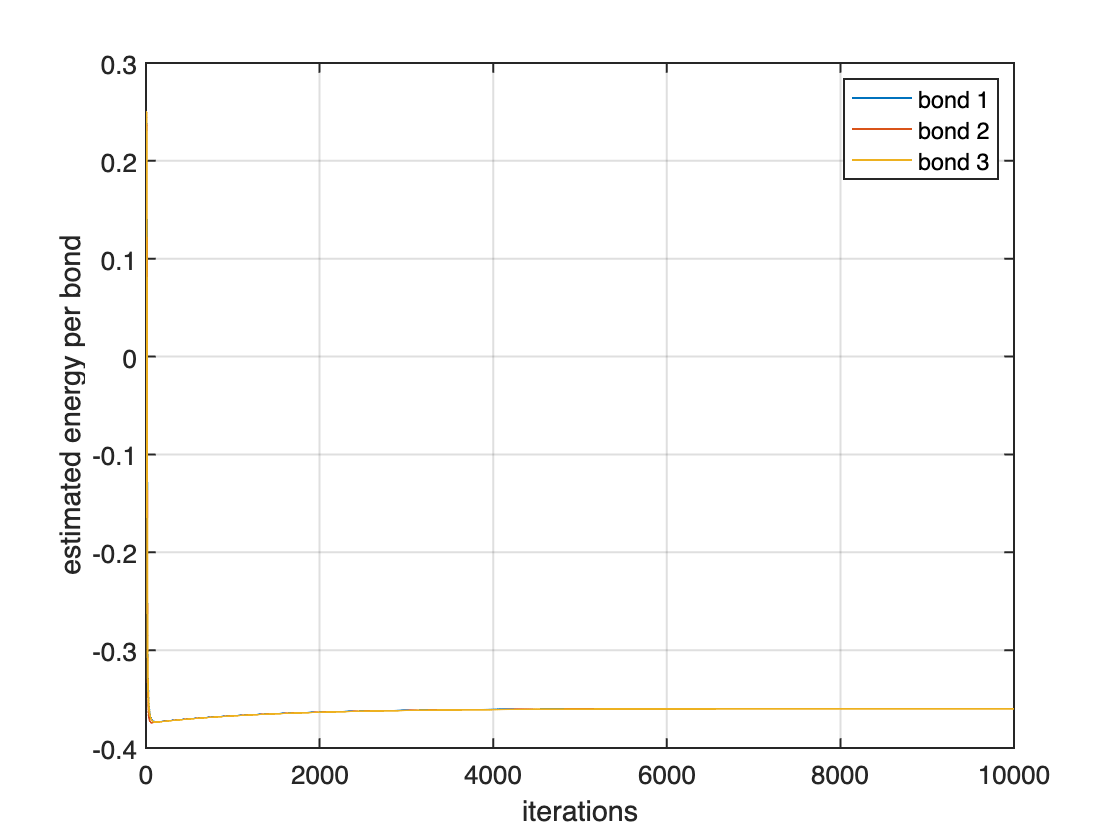

figure;
plot((1:size(Es)).',Es,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13);
grid on;
xlabel('iterations');
ylabel('estimated energy per bond');
legend({'bond 1','bond 2','bond 3'});

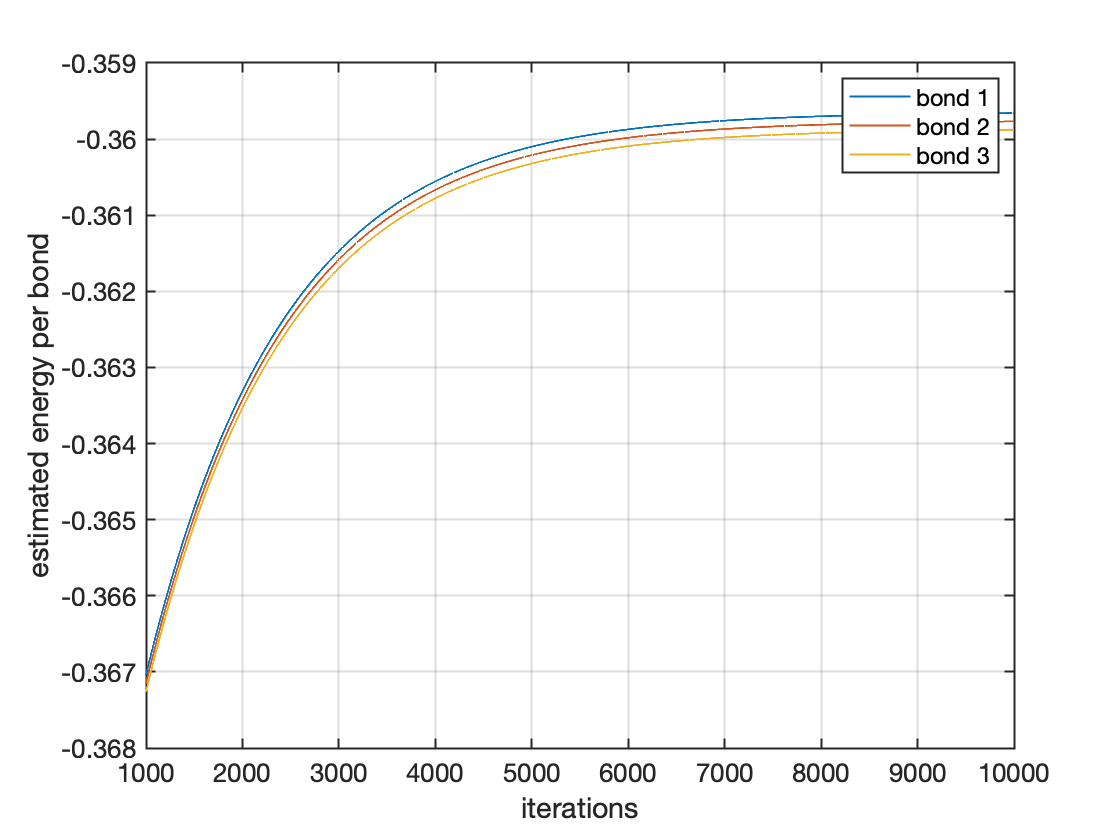

figure;
plot((1:size(Es)).',Es,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13);
grid on;
xlabel('iterations');
ylabel('estimated energy per bond');
legend({'bond 1','bond 2','bond 3'});
xlim([1e3 1e4]);

Note that the fourth output `Es` is the energy measured only with respect to the tensors that are updated. That is, we didn't consider the environment tensors (i.e., the rest of the tensor network except for the tensors that are updated). For many 1D calculations, the MPSs were in canonical forms, so the role of the environment in measuring the energy was trivial. However, here we don't have a canonical form. So the estimated energies in `Es` are inaccurate; as you see, they are even increasing at later iterations!

To get an accurate estimate of the energy, we need to include the environment. For example, the CTMRG is such a method. Here, we use the TRG for the calculation of the ground-state energy.

## Exercise (b): Complete the function for the TRG on a honeycomb lattice

There is a function `TRG_Honeycomb_Ex.m` included in the same sub-directory with this script. The function is designed to contract a network of reduced tensors on an exponentially large honeycomb lattice with periodic boundary conditions. The provided file is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

There are several remarks.

- **Leg order convention**: Inside the function, the tensor legs are permuted to be in counter-clockwise (CC) order and indexed so that the legs of different tensors but with the same indices are contracted together. This leg order convention largely simplifies code writing. 

- **Norm of tensors**: At each RG step, the number of sites in the lattice decreases by 3 in the honeycomb lattice case. Rephrasing, the number of physical sites represented by a single coarse-grained tensor increases by 3 after each RG step. Without proper rescaling, the norm of the tensor may increase as a exponential of an exponential (!) of the RG step iteration. So the total norm often numerically diverges after a few steps. To deal with this numerically, the functions compute the squared norm per lattice site, i.e., $( \langle\Psi | \Psi \rangle )^{1/N}$ where $| \Psi \rangle$ is the total state and $N$ is the number of lattice sites.

- **Last contraction step**: The RG steps are taken until we have a PEPS which is small enough to contract exactly. In this honeycomb case, we contract the last six tensors exactly.

- There is a new function `PEPS/contPlaq.m` which contracts tensors arranged around a plaquette. This function will be useful when one implements the contraction of tensors to get coarse-grained tensors.

Once you finish the above Exercise (b), you can run the following script.

To use the TRG, we reorganize the $\Gamma$ and $\Lambda$ tensors into "usual" rank-4 tensors, each of which sit on a lattice site. We split the $\Lambda$ tensors into their square roots $\sqrt{\Lambda}$, and let each $\sqrt{\Lambda}$ be absorbed into the $\Gamma$ tensors. Then the ground state is expressed by two rank-4 local tensors `TA` and `TB`.

TA = GA; TB = GB;
for it3 = (1:z)
    TA = contract(TA,z+1,it3,diag(sqrt(Lambda{it3})),2,2,[(1:it3-1),z+1,(it3:z)]);
    TB = contract(TB,z+1,it3,diag(sqrt(Lambda{it3})),2,1,[(1:it3-1),z+1,(it3:z)]);
end

Then run the TRG.

E_GS = zeros(3,1); % for three different bond directions
rgstep = 11; % large enough number, to estimate the value in thermodynamic limit
Nkeep2 = 50; % larger bond dimension than in the simple update
[~,E_GS(1)] = TRG_Honeycomb_Ex (TA,TB, ...
    rgstep,Nkeep2,S,permute(conj(S),[2 1 3]));

TERG on a honeycomb lattice: rgstep = 11, Nkeep = 50
22-11-18 14:42:59 | Start
22-11-18 14:44:22 | #01/11
22-11-18 14:44:37 | #02/11
22-11-18 14:44:51 | #03/11
22-11-18 14:45:06 | #04/11
22-11-18 14:45:21 | #05/11
22-11-18 14:45:36 | #06/11
22-11-18 14:45:51 | #07/11
22-11-18 14:46:05 | #08/11
22-11-18 14:46:20 | #09/11
22-11-18 14:46:34 | #10/11
22-11-18 14:46:49 | #11/11
22-11-18 14:46:49 | Squared norm per site = 1.41877, Correlation func. = -0.365723
Elapsed time: 229.9s, CPU time: 1746s, Avg # of cores: 7.597


Note that the last input to `TRG_Honeycomb_Ex` is the Hermitian conjugate of spin operator.

[~,E_GS(2)] = ...
    TRG_Honeycomb_Ex (permute(TA,[2 3 1 4]),permute(TB,[2 3 1 4]), ...
    rgstep,Nkeep2,S,permute(conj(S),[2 1 3]));

TERG on a honeycomb lattice: rgstep = 11, Nkeep = 50
22-11-18 14:46:49 | Start
22-11-18 14:48:08 | #01/11
22-11-18 14:48:22 | #02/11
22-11-18 14:48:37 | #03/11
22-11-18 14:48:51 | #04/11
22-11-18 14:49:06 | #05/11
22-11-18 14:49:20 | #06/11
22-11-18 14:49:35 | #07/11
22-11-18 14:49:50 | #08/11
22-11-18 14:50:05 | #09/11
22-11-18 14:50:22 | #10/11
22-11-18 14:50:39 | #11/11
22-11-18 14:50:39 | Squared norm per site = 1.41877, Correlation func. = -0.365858
Elapsed time: 230.1s, CPU time: 1731s, Avg # of cores: 7.52


[~,E_GS(3)] = ...
    TRG_Honeycomb_Ex (permute(TA,[3 1 2 4]),permute(TB,[3 1 2 4]), ...
    rgstep,Nkeep2,S,permute(conj(S),[2 1 3]));

TERG on a honeycomb lattice: rgstep = 11, Nkeep = 50
22-11-18 14:50:39 | Start
22-11-18 14:52:05 | #01/11
22-11-18 14:52:20 | #02/11
22-11-18 14:52:39 | #03/11
22-11-18 14:52:59 | #04/11
22-11-18 14:53:14 | #05/11
22-11-18 14:53:29 | #06/11
22-11-18 14:53:44 | #07/11
22-11-18 14:53:58 | #08/11
22-11-18 14:54:16 | #09/11
22-11-18 14:54:34 | #10/11
22-11-18 14:54:53 | #11/11
22-11-18 14:54:53 | Squared norm per site = 1.41877, Correlation func. = -0.365993
Elapsed time: 253.5s, CPU time: 1772s, Avg # of cores: 6.991


To obtain the energy across different bond directions, we have rotated the tensors `TA` and `TB` accordingly.

disp(E_GS)

   -0.3657
   -0.3659
   -0.3660



These energy values are close to each other, but not exactly the same. It is similar as that in the iTEBD calculation the even- and odd-bond energies are different and oscillating with iterations. So we average them.

disp(mean(E_GS))

   -0.3659



This is the ground-state energy per bond. On the other hand, Jiang2008 provides the value per site. To make comparison, we multiply 3/2 to the value per bond.

disp(mean(E_GS)*(3/2))

   -0.5488



The error against the published result -0.5506 (for the bond dimension $D=8$, in Jiang2008) is smaller than 0.4%.